**Load CSV data into Matlab Table**

Before you start, clean up the data: NaN are not allowed.

Load a csv file:

% path and file name
path = "/home/andri/repos/ip8-roboter-energy-management/matlab/bat_characterization_data2.csv";
T = readtable(path);

% print first values of the csv file
T   

T = 1162376×3 table
    time     voltage    current
    _____    _______    _______

        0    13.608        0   
    0.161    13.604        0   
    0.263    13.612        0   
    0.367      13.6        0   
    0.469    13.608        0   
    0.573    13.608        0   
    0.678    13.604        0   
    0.779    13.604        0   
    0.881    13.608        0   
    0.984    13.604        0   
    1.086    13.608        0   
    1.188    13.604        0   
    1.291    13.608        0   
    1.392    13.608        0   
    1.498      13.6        0   
    1.601      13.6        0   


Create a new matlab datastructure:

signals(1:3) = struct('values', [], 'dimensions', [], 'label', '');
signals(1).label = "time";
signals(1).values = T.time;
signals(1).dimensions = length(T.time);

signals(2).label = "current";
signals(2).values = T.current;
signals(2).dimensions = length(T.current);

signals(3).label = "voltage";
signals(3).values = T.voltage;
signals(3).dimensions = length(T.voltage);

hppc_mat = struct('signals', signals);

Create a battery pulse sequence object:


% https://ch.mathworks.com/help/autoblks/ug/estimate-equivalent-circuit-lithium-ion-battery-data.html

psObj = Battery.PulseSequence;
psObj.ModelName = 'BatteryEstim2RC_PTBS';
time = hppc_mat.signals(1).values;
current = hppc_mat.signals(2).values;
voltage = hppc_mat.signals(3).values;

psObj.addData(time,voltage,current);

Identify pulses:

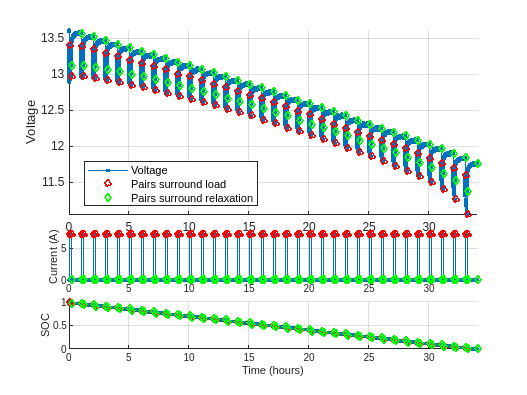

psObj.createPulses(...
    'CurrentOnThreshold',7.0,...
    'NumRCBranches',2,... %how many RC pairs in the model
    'RCBranchesUse2TimeConstants',false,... %do RC pairs have different time constant for discharge and rest?
    'PreBufferSamples',10,... %how many samples to include before the current pulse starts
    'PostBufferSamples',15); %how many samples to include after the next pulse starts

psObj.plotIdentifiedPulses();

% psObj.removePulses(psObj.NumPulses -1);
psObj.plotIdentifiedPulses();

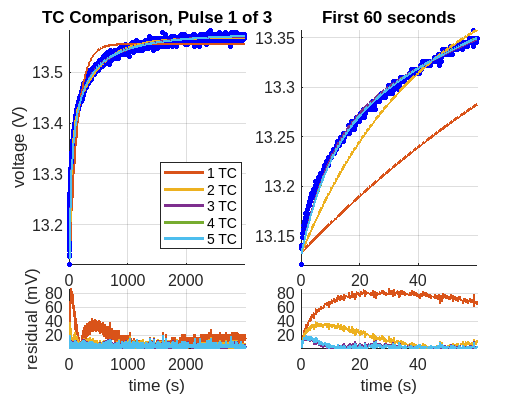

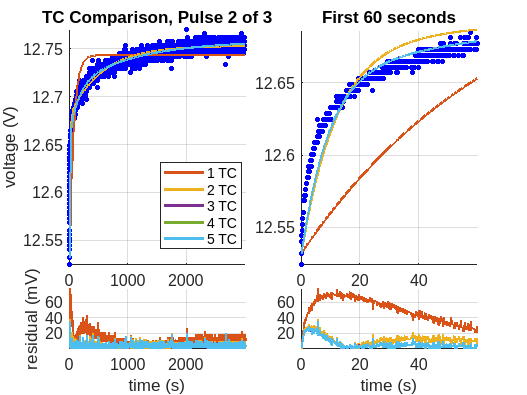

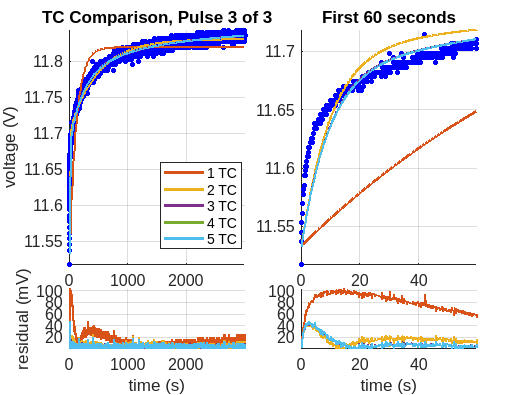


PulsesToTest = [1 floor(psObj.NumPulses/2), (psObj.NumPulses -1)];
psObj.Pulse(PulsesToTest).compareRelaxationTau();

Plot results:

Params = psObj.Parameters;

Params.EmMin(:) = 10.5;

Params.EmMax(:) = 13.8;
Params.Em(:) = 12.8;

Params.Tx(1,:,:) = 7;
Params.Tx(2,:,:) = 50;

Params.TxMin(1,:,:) = 1;
Params.TxMax(1,:,:) = 50;

Params.TxMin(2,:,:) = 20;
Params.TxMax(2,:,:) = 3500;

psObj.Parameters = Params;

disp(psObj);

  PulseSequence with properties:

                 Data: [1162376×5 double]
            ModelName: 'BatteryEstim2RC_PTBS'
             MetaData: [1×1 Battery.MetaData]
             Capacity: 1.4689e+05
           CapacityAh: 40.8031
            NumPulses: 34
             TestType: 'discharge'
                 Time: [1162376×1 double]
              Voltage: [1162376×1 double]
              Current: [1162376×1 double]
               Charge: [1162376×1 double]
             ChargeAh: [1162376×1 double]
                  SOC: [1162376×1 double]
           Parameters: [1×1 Battery.Parameters]
    ParametersHistory: [1×2 Battery.Parameters]
              idxEdge: [136×1 double]
              idxLoad: [34×2 double]
             idxRelax: [34×2 double]
                Pulse: [34×1 Battery.Pulse]




psObj.estimateInitialEmR0(...
    'SetEmConstraints',true,... %Update EmMin or EmMax values based on what we learn here
    'EstimateEm',true,... %Keep this on to perform Em estimates
    'EstimateR0',true); %Keep this on to perform R0 estimates

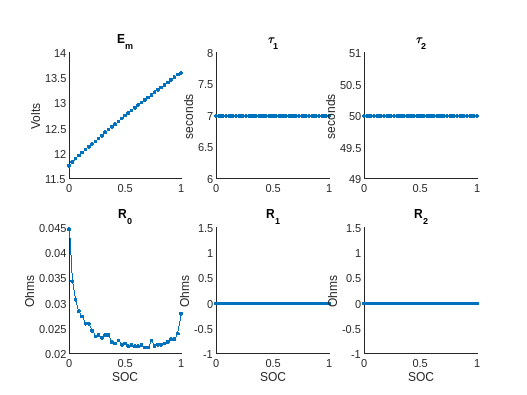

psObj.plotLatestParameters();

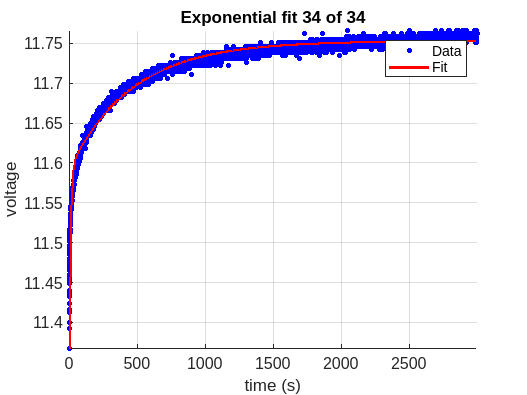


psObj.estimateInitialTau(...
    'UpdateEndingEm',true,... %Keep this on to update Em estimates at the end of relaxations, based on the curve fit
    'ShowPlots',true,... %Set this true if you want to see plots while this runs
    'ReusePlotFigure',true,... %Set this true to overwrite the plots in the same figure
    'UseLoadData',false,... %Set this true if you want to estimate Time constants from the load part of the pulse, instead of relaxation
    'PlotDelay',0.5); %Set this to add delay so you can see the plots 

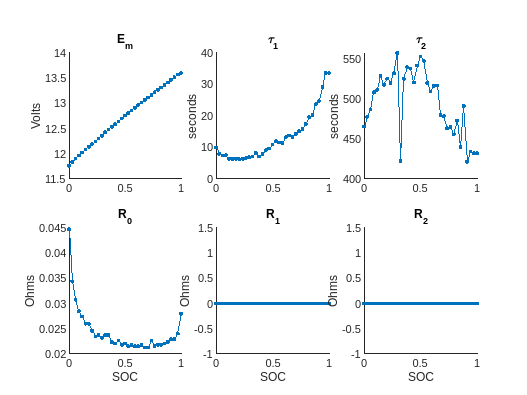


psObj.plotLatestParameters();

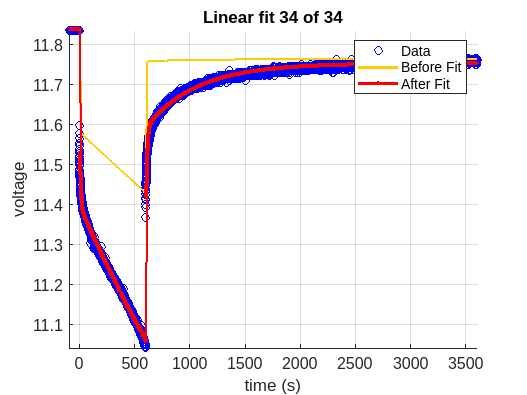


psObj.estimateInitialEmRx(...
    'IgnoreRelaxation',false,... %Set this true if you want to ignore the relaxation periods during this step
    'ShowPlots',true,...  %Set this true if you want to see plots while this runs
    'ShowBeforePlots',true,... %Set this true if you want to see the 'before' value on the plots
    'PlotDelay',0.5,... %Set this to add delay so you can see the plots 
    'EstimateEm',true,... %Set this true to allow the optimizer to change Em further in this step
    'RetainEm',true,... %Set this true keep any changes made to Em in this step
    'EstimateR0',true,... %Set this true to allow the optimizer to change R0 further in this step
    'RetainR0',true); %Set this true keep any changes made to R0 in this step

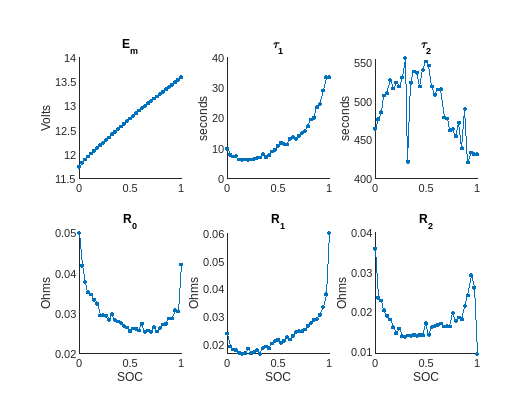


psObj.plotLatestParameters();

Params = psObj.Parameters;

Optimization:

% psObj.plotSimulationResults(); 
% 
% delete(gcp('nocreate'));
% parpool('Processes',4);
% 
% SDOOptimizeOptions = sdo.OptimizeOptions(...
%     'OptimizedModel',psObj.ModelName,...
%     'Method','lsqnonlin',...
%     'UseParallel','always');
% 
% SDOOptimizeOptions.MethodOptions.Display = 'final';
% 
% psObj.estimateParameters(...
%     'CarryParamToNextPulse',true,... %Set this true to use the final parameter values from the prior pulse and SOC as initial values for the next pulse and SOC
%     'SDOOptimizeOptions',SDOOptimizeOptions,... %Specify the SDO options object
%     'ShowPlots',true,... %Set this true if you want to see plots while this runs
%     'EstimateEm',true,... %Set this true to allow the optimizer to change Em further in this step
%     'RetainEm',true,... %Set this true keep any changes made to Em in this step
%     'EstimateR0',true,... %Set this true to allow the optimizer to change R0 further in this step
%     'RetainR0',true); %Set this true keep any changes made to R0 in this step
% 
% 
% psObj.plotLatestParameters();
% psObj.plotSimulationResults();

Export data:

% EmPrime = repmat(Em,2,1)';
% R0Prime = repmat(R0,2,1)';
% SOC_LUT   1Prime = SOC_LUT;
% TempPrime = 303;
% CapacityAhPrime = [CapacityAh];
% R1Prime = repmat(Rx(1,:),2,1)';
% C1Prime = repmat(Tx(1,:)./Rx(1,:),2,1)';
% R2Prime = repmat(Rx(2,:),2,1)';
% C2Prime = repmat(Tx(2,:)./Rx(2,:),2,1)';
vars = {'R0','R1','R2','T1','T2','Em','SOC','P','Q','R'};

R0 = psObj.Parameters.R0'

R0 =     0.0501
    0.0419
    0.0379
    0.0353
    0.0348
    0.0335
    0.0325
    0.0296
    0.0297
    0.0295


R1 = psObj.Parameters.Rx(1,:)'

R1 =     0.0240
    0.0193
    0.0182
    0.0179
    0.0170
    0.0166
    0.0168
    0.0186
    0.0169
    0.0173


R2 = psObj.Parameters.Rx(2,:)'

R2 =     0.0360
    0.0237
    0.0229
    0.0205
    0.0191
    0.0182
    0.0163
    0.0147
    0.0160
    0.0140


SOC = psObj.Parameters.SOC

SOC =          0    0.0294    0.0588    0.0882    0.1176    0.1471    0.1765    0.2059    0.2353    0.2647    0.2941    0.3235    0.3529    0.3824    0.4118    0.4412    0.4706    0.5000    0.5294    0.5588    0.5882    0.6176    0.6471    0.6765    0.7059    0.7353    0.7647    0.7941    0.8235    0.8529    0.8823    0.9118    0.9412    0.9706    1.0000


T1 = psObj.Parameters.Tx(1,:)'

T1 =    10.0003
    8.0375
    7.4433
    7.5754
    6.4206
    6.3602
    6.4183
    6.3031
    6.4222
    6.6133


T2 = psObj.Parameters.Tx(2,:)'

T2 =   465.2529
  477.5803
  486.4661
  508.1025
  511.1241
  528.3908
  517.3401
  525.0666
  519.7735
  531.6536


Em = psObj.Parameters.Em'

Em =    11.7524
   11.8333
   11.9037
   11.9651
   12.0290
   12.0846
   12.1418
   12.1961
   12.2457
   12.3038



R0 = repmat(R0,1,2);
R1 = repmat(R1,1,2);
R2 = repmat(R2,1,2);
T1 = repmat(T1,1,2);
T2 = repmat(T2,1,2);
Em = repmat(Em,1,2);

T = [300, 301]

T =    300   301



P = diag([1e-6 1e-6 1]); 
Q = 1e-4 * eye(3); % uncertainty of process model
R = 0.7 % uncertainty of measuremtents

R = 0.7000

AH = 44

AH = 44

Ts = 0.1

Ts = 0.1000

Load simulation data as timeseries into workspace for ROS2 simulation publisher:

Scope Settings > Logging: variable_name = voltage_current_sim_data

u = out.voltage_current_sim_data.signals(1).values

Unable to resolve the name 'out.voltage_current_sim_data.signals'.

i = out.voltage_current_sim_data.signals(2).values
t = out.voltage_current_sim_data.time

u = timeseries(u,t)
i = timeseries(i,t)

plot(u)
i.Length
i
plot(i.Data(10:10000))